# lora sim script

## lora parameters

%clear;
SF=7; %spreading factor 7-12
Fs=125e3;%samplingrate = BW
SPS=2^SF;%samples per symbol



## sim parameters

%data
% numSym=round(10000/SF);
numSym=840;

randomData=false;
%channel
perfectChannel=false;%no  awgn
maxDopplerShift=0.45*Fs/(2^SF);%shift has to be less than 0.5*Fs/(2^SF) to have no impact
flatDoppler=true;%true: apply same shift to entire signal, false: gradient from +maxShift to -maxShift over length of signal
maxSNR=5; %signal to noise ratio in dB
%loops
nLoops=20;
loopSNR=true;
SNRstepsize=2;
loopDoppler=false;
dopplerStepsize=0.1e3;

plotSpectrogram=true;

## tx

%generate data
dataLength=numSym*SF;% SF bits per symbol
if randomData
    messageBits= randi([0 1],dataLength,1);
else
    symbol=10;%generate symbols with certain value
    messageBits=transpose(repmat(dec2bin(symbol,SF)-'0',1,numSym));% -'0' to convert binary string to vector
end
%generate lora signal
[loraSignal,decimalSymbols]=generateLoraSignal(messageBits,SF,numSym);
decimalSymbols

decimalSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


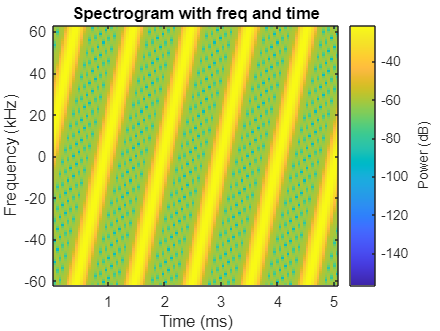

if plotSpectrogram
    %spectroram of first 5 symbols
    figure
    windowLength=round((SPS)/10);
    spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
    title('Spectrogram with freq and time')
    % figure
    % spectrogram(loraSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
    % title('Spectrogram with freq index and samples')
end

## channel & rx

decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    48    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10    10


decodedSymbols =     10    10    10    10    10    10    10    10    10    10    10     9    10   107    10    10    10    10    10    10    10    10    10    10    10    10    74    10    27    10    10     0    10    10    10    10    10    10    10    10    10    10    10    10   121    44    10    10    10   111


decodedSymbols =     10    10    10    10    10    85    33    10    44    10    10    10    10    10     1   104    39   117    10    10    49    10    10    10    10    10    10    10    10    10   104    10    10    10    10    10    52    10    10    10    15    10    10    10   103    10    10    10    10    35


decodedSymbols =      1    13    35    10    10    10    58    75    10    10    10    70    11    39    59    34    30    10    70    18    44    10   117    10   118    35    10     6    55   112    10    10    10     5   109    10    10   102    75    10    10   123    20    24    10    10    94    66    10    10


decodedSymbols =     10    55    69    14    85   104    68    15   105    57    99    15    10   115    33    60    16    62    10    69     2    10    10    74    63     2    59   117    75    94    67   116    16    10     6    57    99   117    10    36    67    61    80    20    59   119   120    17     4    10


decodedSymbols =     49    52    37   119    69    50    75    75    96    16   102    16   111    97   115    49    93     4   119    55   117    76    36    10   124   127    39    65    10    10    81    21    30    19   104   126    90    37    67   111    93    76    79    51    59    26    10    71   100   121


decodedSymbols =     11    97    74    85    79   126    64    63    18    29     0    56    89    96     3   125    53    46    54    46    47    10    88     0    44    31    58    24    65     2    45    26    17    66    44    10    50   122    21    71   113    10    51    16    69    20    94   102    10   102


decodedSymbols =    116    69   101   114    59   105   116   112    26   124    62    59    20   109    56     5    93   116   105    20    36    64    83    71   104    60     8   110   105    27    42    33    28    29    17   108    20    18    33    86    93    86    27    49    99    44    83    36    11    90


decodedSymbols =     53    64    10    81    15    47    70   107     9    75   107    23   123   118   106   100    98    94    57   103    14    43    11   112    39   105     4    78    31    33    22    20    32    25     9    53    17    63    19     6    22   101    16    48    91    47    63   109    79    41


decodedSymbols =     79    99   119    76    90    94   112     0    69    45    24    29    52    98    70    65    47   107    76    20    87    86    75    52    90    64    59     3    19    86   107   104    91   121   125    10    26    91    44    21   100   125    53    29   105    53     3    99    33   103


decodedSymbols =     19    40    74   119    92   106    90   108    74    65   127   109   114   104   119   112     6    40     8    50    77    64     0    59     6    44     6    34    19     4    91    56    37     0     1   118    95     4    67    85   120    42    78   115    89    74    56    28    93    81


decodedSymbols =     79    46    23    31    94   112    22    22    12    38    27    66    36    75    94    52   100    54    16    61    53    72   126    45   125   102   121    60    90    86    23    80    36    77   102    44    28    21   111    14     1   110   108    67     7    28    53    86    80     0


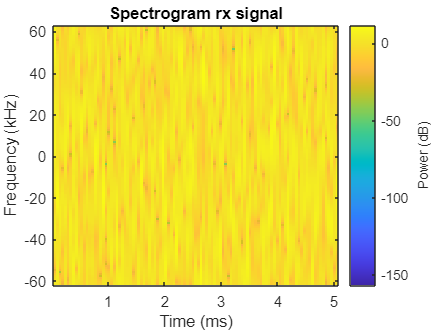

decodedSymbols =     78    49    79    93    97    28   108    31   103    50    27   118    15    84    53     4    78   106    48    46    96    63    27   122    66   126   106   103    16    14    75    67    65    73    45   121    43   102    59    19    22    47    26    63    73    92    32   125   126    83


%channel
for counter=1:nLoops


    symbolDuration=(2^SF)/Fs;

    t=(symbolDuration/2^SF:symbolDuration/2^SF:symbolDuration*numSym);
    
    if flatDoppler
        freqShift=maxDopplerShift;
    else
        freqShift=linspace(dopplerShift,-dopplerShift,length(t));
    end
    dopplerEffect = exp(1i * 2 * pi * freqShift.* t);
    if perfectChannel% use maxDopplerShift = 0 for truly perfect channel
        rxSignal = loraSignal.* (dopplerEffect);
    
    else
        if loopSNR
            rxSignal=(awgn(loraSignal,maxSNR-(counter-1)*SNRstepsize,'measured'));
        else
            rxSignal=(awgn(loraSignal,maxSNR,'measured'));
        end
        %snr
    end

    if (plotSpectrogram && counter==nLoops)
        %spectroram of first 5 symbols
        figure
        windowLength=round((SPS)/10);
        spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,Fs,'power', 'centered','yaxis');
        title('Spectrogram rx signal')
        % figure
        % spectrogram(rxSignal(1:min(5*SPS,numSym*SPS)),windowLength,round(windowLength/2),SPS,SPS,'power','yaxis');
        % title('Spectrogram with freq index and samples')
    end

    %rx
    [decodedBits,decodedSymbols]=demodulateLoraSignal(rxSignal,SF,numSym);
    decodedSymbols
    errors(counter)=sum(messageBits~=decodedBits);
end

## ber

'Adaptive Parameters for LoRa-Based Networks Physical-Layer' for ber formula

%lora_ber=errors/dataLength
lora_ser=sum(transpose(decimalSymbols~=decodedSymbols))/numSym

lora_ser = 0.9929

lora_ber7=errors/dataLength

lora_ber7 =          0         0         0         0         0         0    0.0014    0.0041    0.0556    0.1651    0.3012    0.3968    0.4471    0.4622    0.4762    0.4920    0.4951    0.4779    0.5002    0.5029


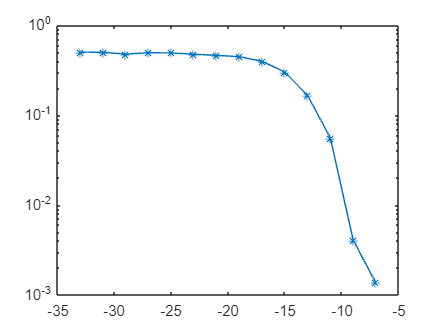

Unrecognized function or variable 'lora_ber12'.

% lora_ber9=errors/dataLength
% lora_ber12=errors/dataLength

if loopSNR
    figure
    
    SNRvec=flip((maxSNR-(nLoops-1)*SNRstepsize):SNRstepsize:maxSNR);
    theoryBer12=qfunc((log(12)/log(12))/sqrt(2)*(SNRvec+10*log10((2^12)/12)));
    
    theoryBer7=qfunc((log(7)/log(12))/sqrt(2)*(SNRvec+10*log10((2^7)/7)));
    % semilogy(SNRvec',theoryBer12,'-*')
    % hold on
    % semilogy(SNRvec',theoryBer7,'-*')
    semilogy(SNRvec',lora_ber7,'-*')
    hold on
    % semilogy(SNRvec',lora_ber9,'-*')
    semilogy(SNRvec',lora_ber12,'-*')
    semilogy(SNRvec',nbiot_ber,'-*')
    grid on
    xlabel('SNR (dB)')
    ylabel('Bit Error Rate')
    ylim([10e-5 1])
    %legend('theory 12','theory 7','SF 7','SF 9','SF 12')%adjust legend!
    legend('SF 7','SF 12','nbiot')
    
end


%% compare with nbiot


## doppler corection

shifting the signal with n kHz will shift the demodulated symbol with (dopplerShift/BW)*SF

e.g. with SF=7, symbol 0 will be demodulated as 66 when the signal is shifted with 64 kHz 

original symbol = received symbol -(dopplerShift/125kHz)*SF)

to estimate frequency shift: ((receivedSymbol-expectedSymbol)/SF)*BW